# **Project 1**

BENG280A FQ23 Group#23

Due: 11/8/2023

## Set up a phantom to scan

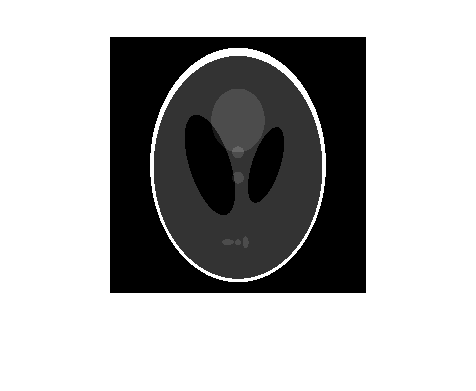

p = phantom(256);
imshow(p)

## Set up scan type

scan_type = "parallel";
if scan_type == "parallel"
    scan = @(x) radon(x,0:1:180); % default angle 0:1:180
    iscan = @(x) iradon(x, 0:1:180);
else
    scan = @(x) fanbeam(x, 250); % default distance 250
    iscan = @(x) ifanbeam(x, 250);
end

## Scan phantom

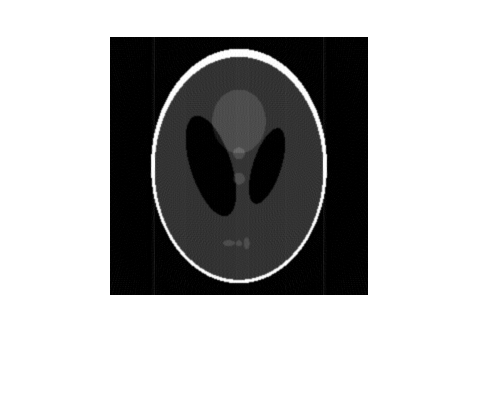

sinogram = scan(p);
imshow(iscan(sinogram))

## Simulate movement

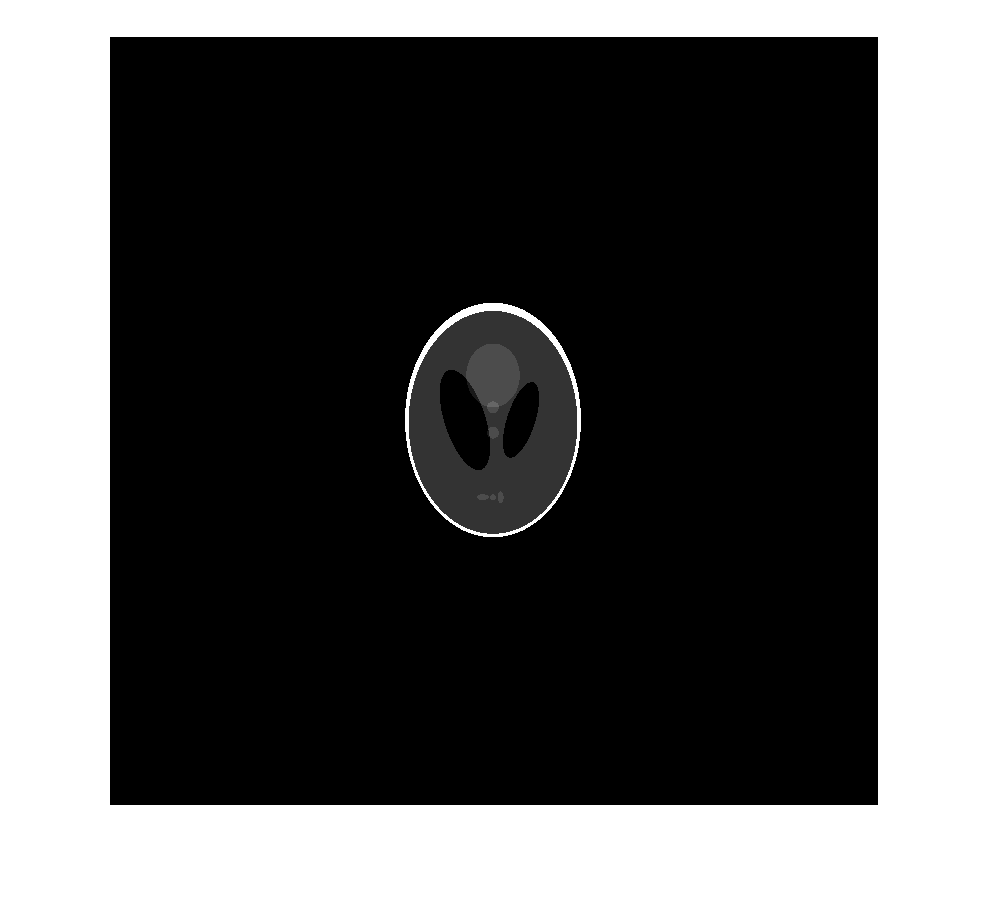

% generate a field in which the subject moves and/or rotate
field = zeros(size(p)*3);
xloc = length(field)/2; % where the subject locates in image
yloc = xloc;

imshow(draw(field, p, yloc, xloc))

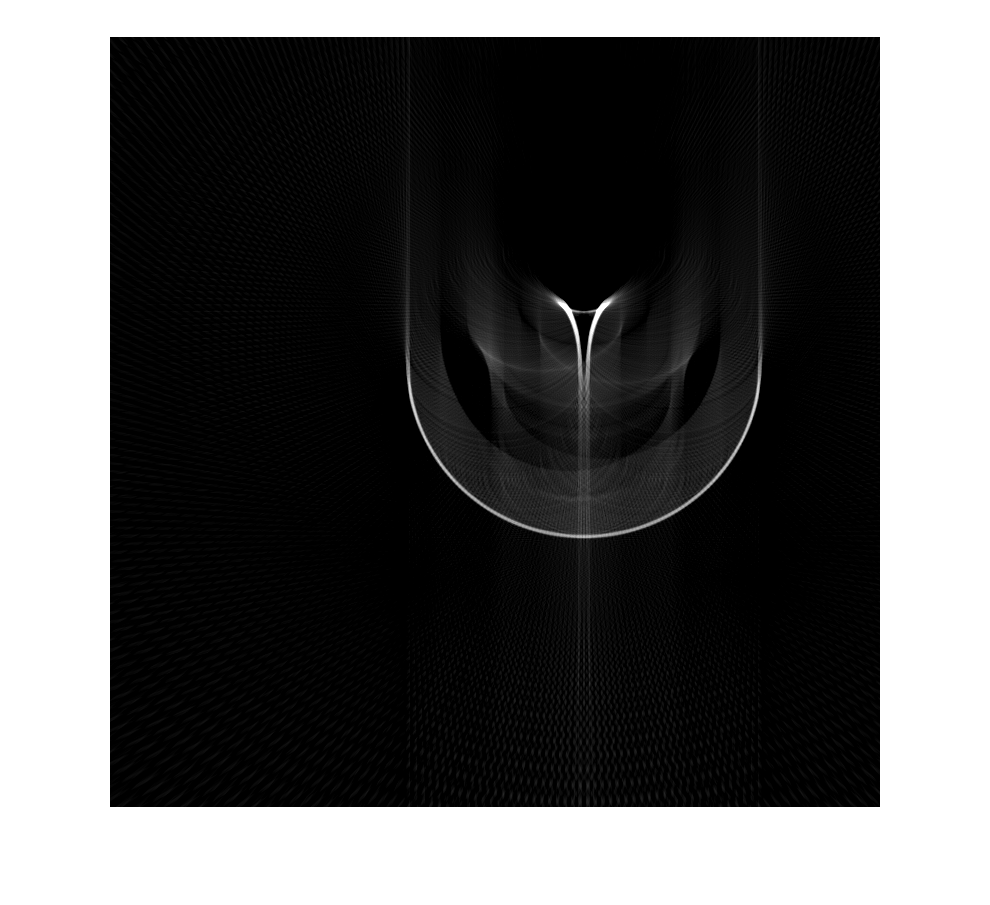

initial_scan = scan(draw(field, p, yloc, xloc)); % create initial sinogram array matrix

for theta = 0:1:180
    img_temp = draw(field, p, yloc, xloc);
    scan_temp = scan(img_temp);
    initial_scan(:, theta+1) = scan_temp(:, theta+1);
    xloc = xloc + 1;
end

imshow(iscan(initial_scan))

## Expand/Compress (Circle)

#### Variables

imSize = [256 256];     % [px px] 256 x 256 image [x y]
fCT = 20;             % [Hz] frequency CT, angles per second
fExp = 15/60;           % [Hz] rate of expansion/compression (human lungs 12~15 breaths/min)
cen = [128 128];        % [px px] center of image [x y]
radi = 60;              % [px] starting radius of circle (assuming compressed)
imgOut = 7;             % [px] outline thickness
expand = round(radi*(2^(1/3))) - radi;            % [px] difference in radius btwn smallest/largest circles (human lungs double in volume?)

#### Creating Image

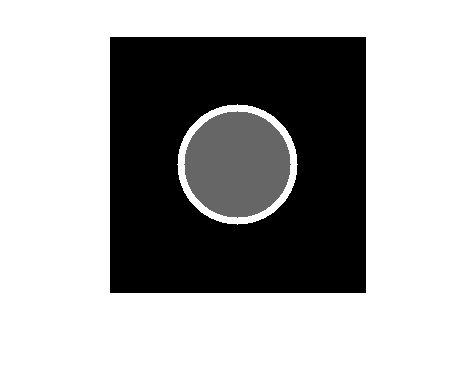

aNum = 181;               % # angles (181)
tCT = aNum/fCT;         % [s] total time of CT scan (# angles * angle freq)
tPx = 2*expand*fExp;        % [px/s] rate of change in radius
totalPx = 0:(tCT/aNum):tCT;    % total time (tCT) in increments of time corresponding to rate of change in angle

sComp = zeros(imSize(1), imSize(2), aNum+1);     % array to store all images per angle (including starting image)
[imCol, imRow] = meshgrid(1:imSize(1), 1:imSize(2));    % to use in making circle/ellipse
filename = "ExpCompCircle.gif";       % exp/comp output gif

% Computing and recording image motion for duration of scan
for i=1:length(totalPx)     % increment at sampling times for each angle
    ovR = tPx*totalPx(i);       % overall change in radius
    modDiv = mod(ovR, expand);  % modulo of overall change in radius by max expansion
    intDiv = (ovR-modDiv)/expand;   % integer division using modulo
    
    % find expansion/compression at time of sampling
    rCurr = radi + expand*(mod(intDiv,2)) + modDiv*(-1)^((ovR-modDiv)/expand);
    
    % Computing projection image at time of sampling
    outC = ((imRow - cen(1)).^2 + (imCol - cen(2)).^2) <= rCurr.^2;
    inC = ((imRow - cen(1)).^2 + (imCol - cen(2)).^2) <= (rCurr - imgOut).^2;
    sComp(:, :, i) = outC - inC*(1-0.4);
    
    if i==1
        imwrite((sComp(:, :, i)*255 +1), filename, "gif", "Loopcount", Inf, "DelayTime", (tCT/aNum));
    else
        imwrite((sComp(:, :, i)*255 +1), filename, "gif", "WriteMode", "append", "DelayTime", (tCT/aNum));
    end
end
imshow(sComp(:,:,1))        % image at starting time

#### Scanning

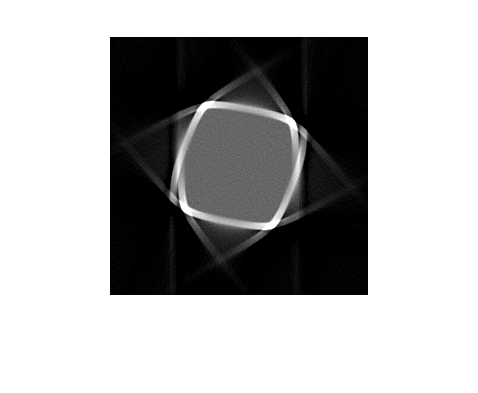

sinoC = scan(sComp(:,:,2));     % initializing sinogram at angle 0 deg

for theta = 2:1:aNum        % increment through angles 1-180 deg
    scanC = scan(sComp(:,:, theta+1));
    sinoC(:, theta) = scanC(:, theta);  % replacing "slices" of sinogram with image at time corresponding to angle
end

imshow(iscan(sinoC))    % reconstruct image